close all; clear; clc;

# Motor Test Stant Practice Data Set

**filename:** test20180625.mlx

**keywords:** Motor test stand, characterize test stand

**file created by **20180625 Kendy Edmonds

**last updated on** 20180629

**primary purpose:** Come up with a standardized way to import, plot and analyize data collected from the test stand.

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes: **I changed the P input for the C_P function saved in this file to P_out. Need to verify this is correct. 

rot_speed is in rad/sec, need to makes sure this is correct for all calculations

*Need to verify that mechanical power recorded by test stand is the same thing as P_out. Do this by comparing to (Q*rot_speed)*

                     ***UPDATE***: (20180626) Input_P is approximately the same as the calculation of (measured) Input_V * (measured) Input_A. Measured Mechanical power is NOT the same as P_out calculated (by Q*rot_speed). Mechanical power is significantly higher. **It might be a good idea to ask the RC Benchmark guys how Mechanical Power is calculated or measured**

Does ESC_us translate to throttle % somehow? How to we compare Tom's charts that use throttle % to what the test stand records?

The order of the variables out of the data should be the same, but row #3 needs to be deleted before it is saved as a .mat file (servo- isn't used)

## Initial Variables

% Density of air in lab on 20180625
p = 0.002300794954;             % slugs/ft^3

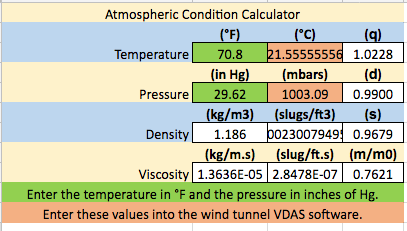

Screen capture of calculator used to obtain density

% Motor specs
radius = 0.625;               % [ft]
area = pi * radius^(2);       % [ft^2]


## Measured Data

load('alltestvalues.mat');
time = alltestvalues(:,1);          % [sec]
ESC_us = alltestvalues(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = alltestvalues(:,3);             % [ft.lbf]
T = alltestvalues(:,4);             % [lbf]
Input_V = alltestvalues(:,5);       % [Volts]
Input_A = alltestvalues(:,6);       % [Amps]
rot_speed = alltestvalues(:,7);     % [rad/sec]
P_in_W = alltestvalues(:,8);       % [Watts]
P_out_W = alltestvalues(:,9)          % [Watts]

P_out_W =          0
    1.5026
    6.0441
   13.0870
   22.5953
   33.1444
   45.7549
   40.3101
   40.3395
   40.5994



P_out = P_out_W .* 0.7478;            % convert to [ft.lbf/sec]
P_in = P_in_W .* 0.7478;

Motor_Eff = alltestvalues(:,10);    % [%]
Prop_Eff = alltestvalues(:,11);     % [lbf/Watts]
Overall_Eff = alltestvalues(:,12);  % [lbf/Watts]  
Motor_Temp = alltestvalues(:,13);   % [F]


% Calculated data
P_out_cal = Q .* rot_speed

P_out_cal =          0
    1.1085
    4.4568
    9.6508
   16.6648
   24.4450
   33.7440
   29.7289
   29.7571
   29.9457


P_in_cal = (Input_V .* Input_A) .* 0.7478

P_in_cal =    -0.0292
    4.2493
   10.1513
   18.2953
   28.1841
   38.9946
   50.8469
   44.4639
   44.3672
   44.7460


## Thrust, Power, and Torque Coefficents

[C_T] = Thrust_Coefficient(T,p,area,rot_speed,radius);
[C_P] = Power_Coefficient(P_out,p,area,rot_speed,radius);
[C_Q] = Torque_Coefficient(Q,p,area,rot_speed,radius);

## Plots

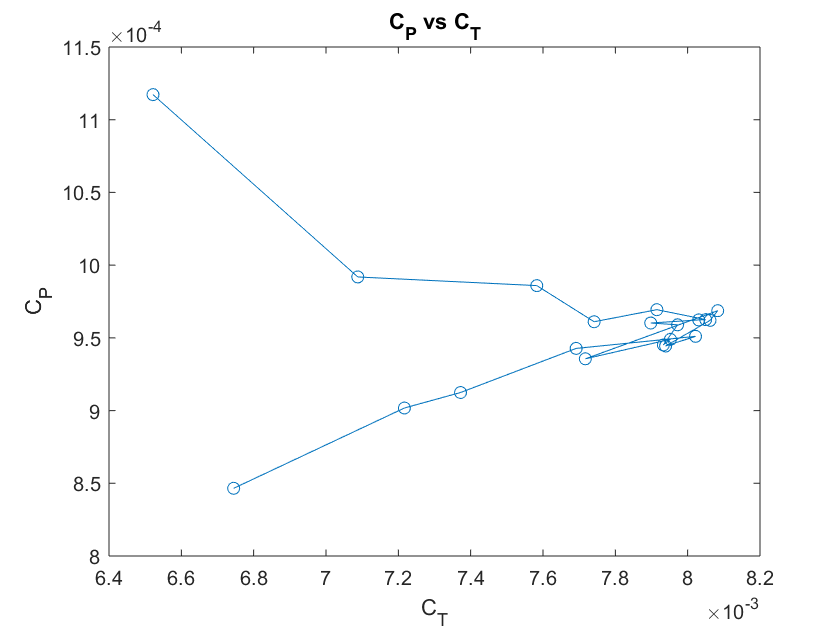

figure(1)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

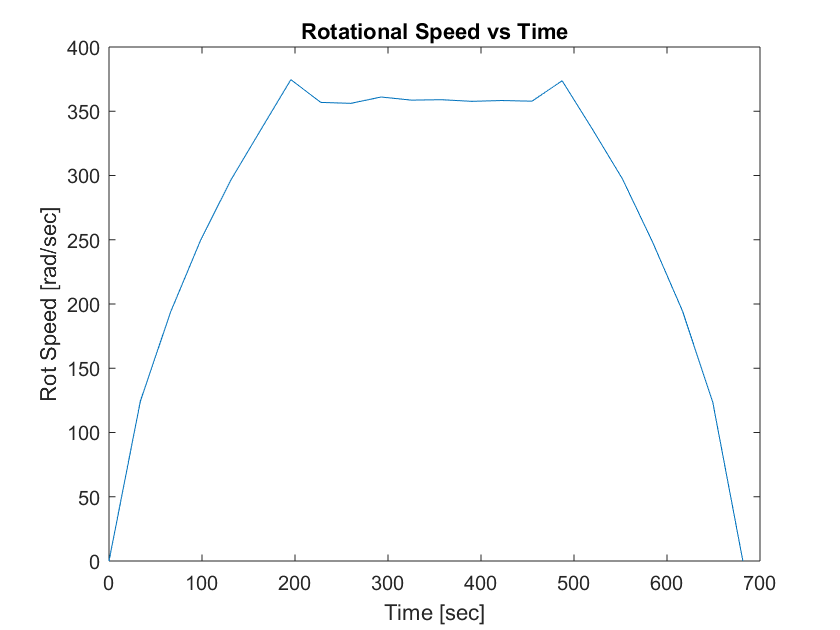

figure(2)
plot(time, rot_speed);
title('Rotational Speed vs Time'); xlabel('Time [sec]'); ylabel('Rot Speed [rad/sec]')

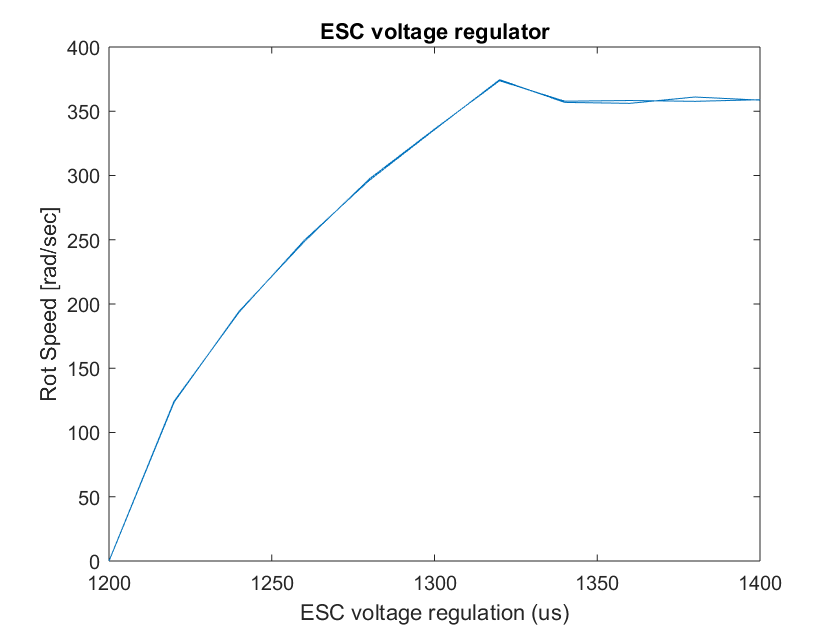

figure(3)
plot(ESC_us, rot_speed);
title('ESC voltage regulator'); xlabel('ESC voltage regulation (us)'); ylabel('Rot Speed [rad/sec]')

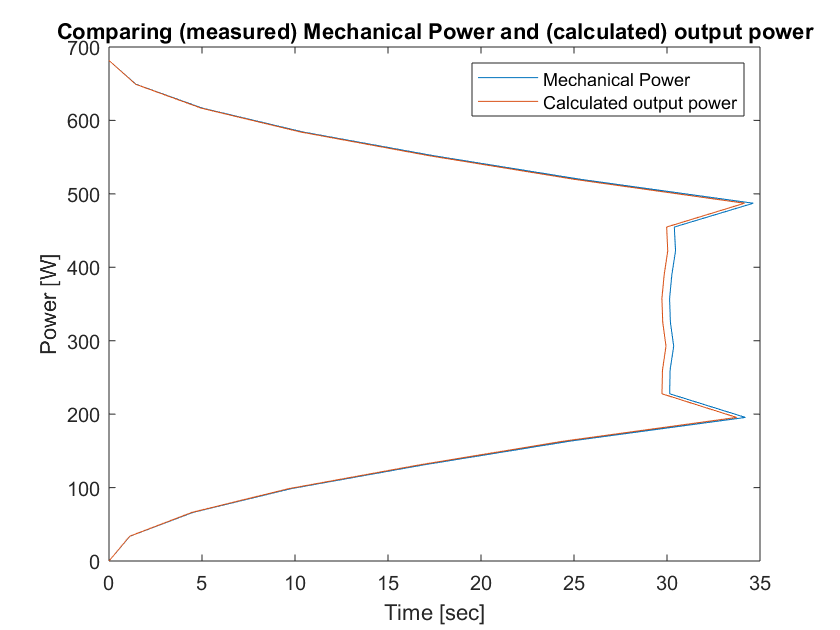

% Figure shows that Mechanical Power (P_out) is consistent with calculation of ouput power (Q*rot_speed)
figure(4)
plot(P_out, time, P_out_cal,time);
title('Comparing (measured) Mechanical Power and (calculated) output power'); xlabel('Time [sec]'); ylabel('Power [W]')
legend('Mechanical Power','Calculated output power')

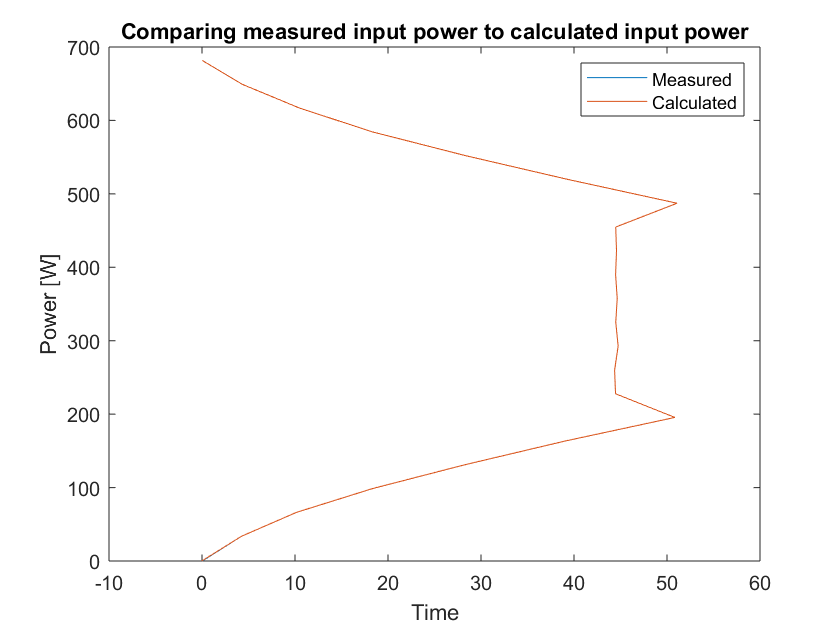

% Figure shows that input power measurement is accurate with calculated
figure(5)
plot(P_in ,time, P_in_cal,time)
title('Comparing measured input power to calculated input power'); xlabel('Time'); ylabel('Power [W]')
legend('Measured','Calculated')

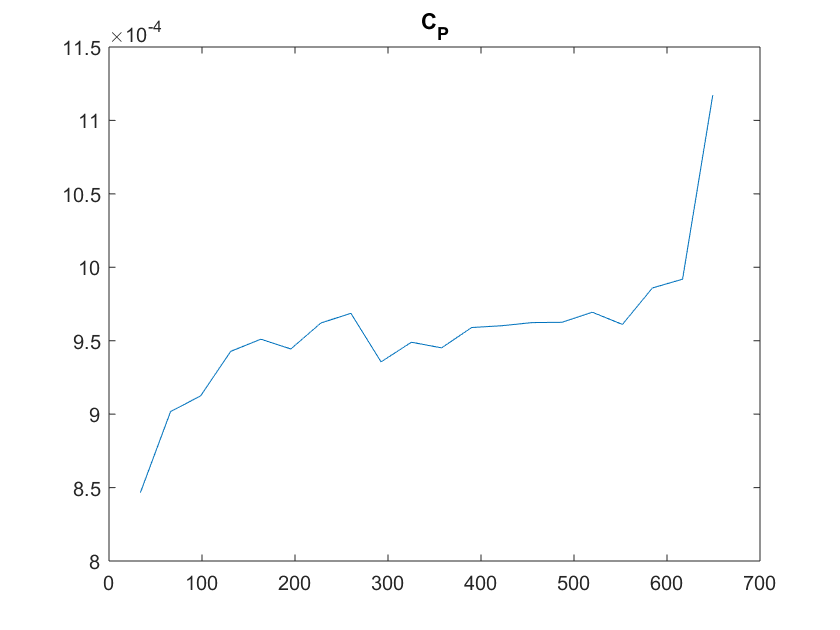

figure(6)
plot(time, C_P);
title('C_P');

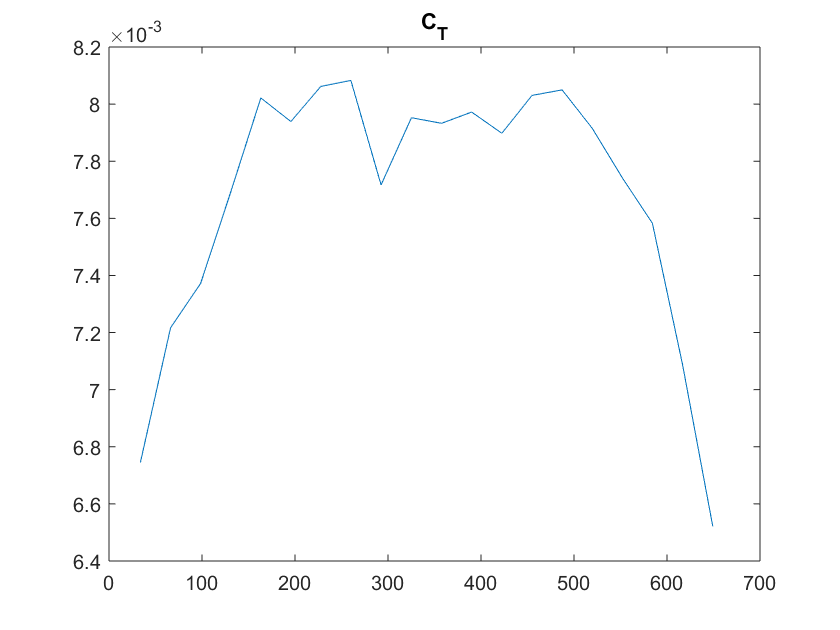


figure(7)
plot(time, C_T);
title('C_T');

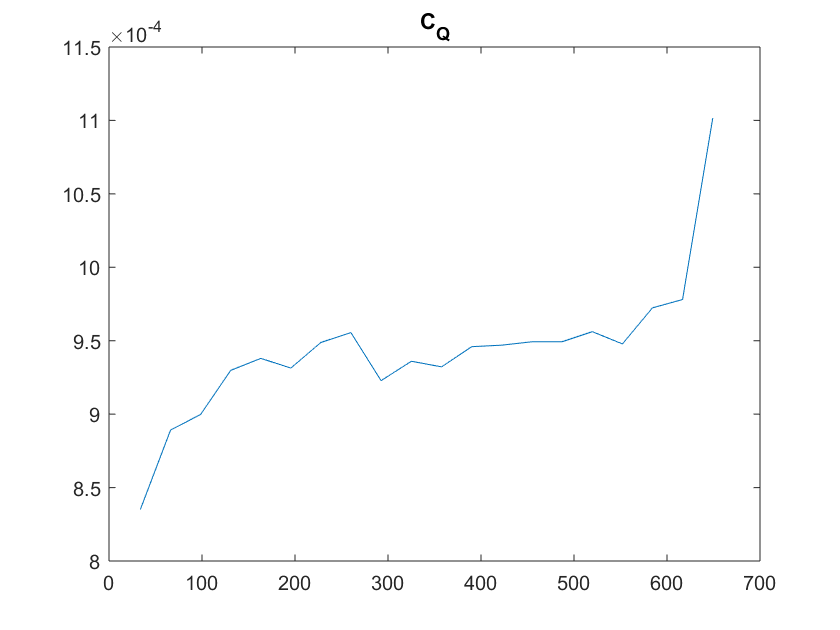


figure(8)
plot(time, C_Q);
title('C_Q');

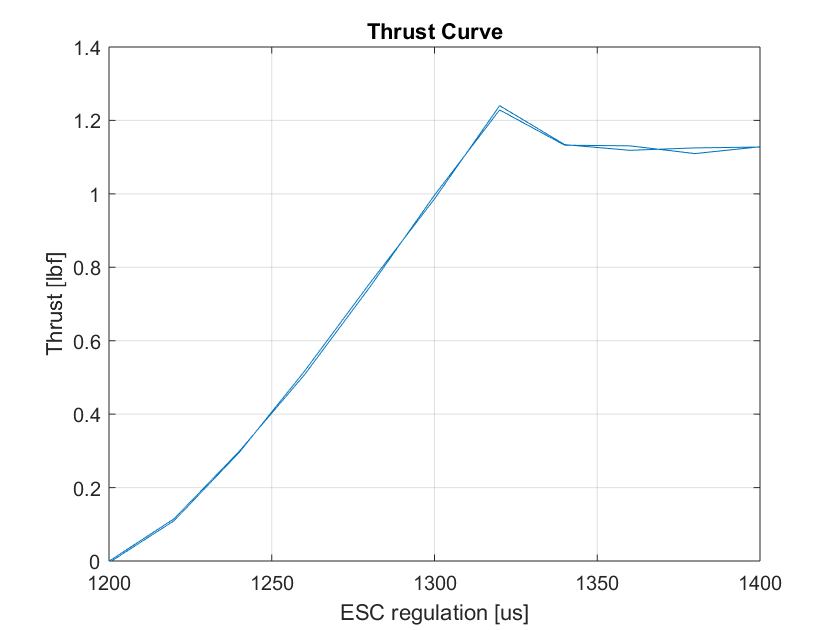

figure(9)
plot(ESC_us, T);
title('Thrust Curve'); xlabel('ESC regulation [us]'); ylabel('Thrust [lbf]'); 
grid('on'); ylim([0,1.4]);